## Sensor Data & Initialisation

clear; clc;
temperature = 24;
soc = 65;
[s_box, inv_s_box, w, poly_mat, inv_poly_mat] = aes_init;

 
********************************************
*                                          *
*       S - B O X   C R E A T I O N        *
*                                          *
*   (this might take a few seconds ;-))    *
*                                          *
********************************************
 
    s_box : 63 7c 77 7b f2 6b 6f c5 30 01 67 2b fe d7 ab 76 
            ca 82 c9 7d fa 59 47 f0 ad d4 a2 af 9c a4 72 c0 
            b7 fd 93 26 36 3f f7 cc 34 a5 e5 f1 71 d8 31 15 
            04 c7 23 c3 18 96 05 9a 07 12 80 e2 eb 27 b2 75 
            09 83 2c 1a 1b 6e 5a a0 52 3b d6 b3 29 e3 2f 84 
            53 d1 00 ed 20 fc b1 5b 6a cb be 39 4a 4c 58 cf 
            d0 ef aa fb 43 4d 33 85 45 f9 02 7f 50 3c 9f a8 
            51 a3 40 8f 92 9d 38 f5 bc b6 da 21 10 ff f3 d2 
            cd 0c 13 ec 5f 97 44 17 c4 a7 7e 3d 64 5d 19 73 
            60 81 4f dc 22 2a 90 88 46 ee b8 14 de 5e 0b db 
            e0 32 3a 0a 49 06 24 5c c2 d3 ac 62 91 95 e4 79 
          

## Plaintext Message Creation

plaintext_msg = "{T:" + temperature + "C, SOC:" + soc + "%}"

plaintext_msg = "{T:24C, SOC:65%}"

plaintext = convertStringsToChars(plaintext_msg);

## Encryption

ascii_plaintext = double(plaintext)

ascii_plaintext =    123    84    58    50    52    67    44    32    83    79    67    58    54    53    37   125


ciphertext = cipher(ascii_plaintext, w, s_box, poly_mat, 1)

 
********************************************
*                                          *
*               C I P H E R                *
*                                          *
********************************************
 
Initial state :                  7b 34 53 36 
                                 54 43 4f 35 
                                 3a 2c 43 25 
                                 32 20 3a 7d 
 
Initial round key :              00 04 08 0c 
                                 01 05 09 0d 
                                 02 06 0a 0e 
                                 03 07 0b 0f 
 
State at start of round 1 :      7b 30 5b 3a 
                                 55 46 46 38 
                                 38 2a 49 2b 
                                 31 27 31 72 
 
After sub_bytes :                21 04 39 80 
                                 fc 5a 5a 07 
                                 07 e5 3b f1 
                                 c7 cc c7 40 
 
After shift_rows :         

ciphertext =     37   254   254     2    17   155    51     2    13   137    51   121   159   167   152    43


char(ciphertext)

ans =     '%þþ3
     3y§+'


## Modulation (Chirp Spread Spectrum)

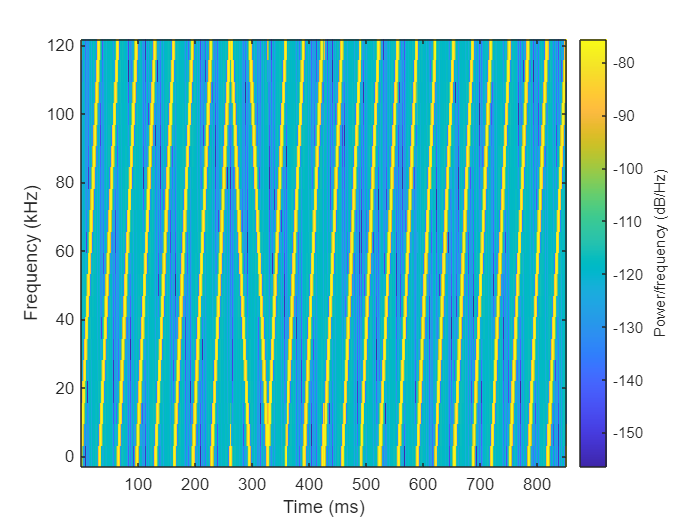

SF = 12;       % Spreading factor
BW = 125e3;    % Bandwidth
Fs = 125e3;    % Sampling frequency
SNR = -15;     % Signal to Noise ratio (db)
num_samples = (2^SF)*Fs/BW;
data = [0 0 0 0 0 0 0 0 -1 -1 ciphertext]; % 0: Up chirp, -1: Down chirp
signal_data = zeros(length(data), num_samples);
clean_data = zeros(length(data), num_samples);

% Modulation
for i = 1:length(data)
    k = data(i);
    lora_symbol = zeros(1, num_samples);
    if k == -1      % Generate down-chirp
        k = 0;
        for n = 1:num_samples
            k = k+1;
            lora_symbol(n) = (1/(sqrt(2^SF)))*exp(-1i*2*pi*(k)*(k/(2^SF*2)));
        end
    else    % Generate symbol
        for n = 1:num_samples
            if k >= 2^SF        % Apply modulo
                k = k-2^SF;
            end
            k = k+1;
            lora_symbol(n) = (1/(sqrt(2^SF)))*exp(1i*2*pi*(k)*(k/(2^SF*2)));
        end
    end
    
    clean_data(i, :) = lora_symbol;

    % Add Gaussian white noise
    lora_symbol = awgn(lora_symbol, SNR, 'measured');
    signal_data(i, :) = lora_symbol;
end

seg_len = 20;
spectrogram(reshape(clean_data', 1, numel(clean_data))', seg_len, [], seg_len, Fs, 'yaxis');

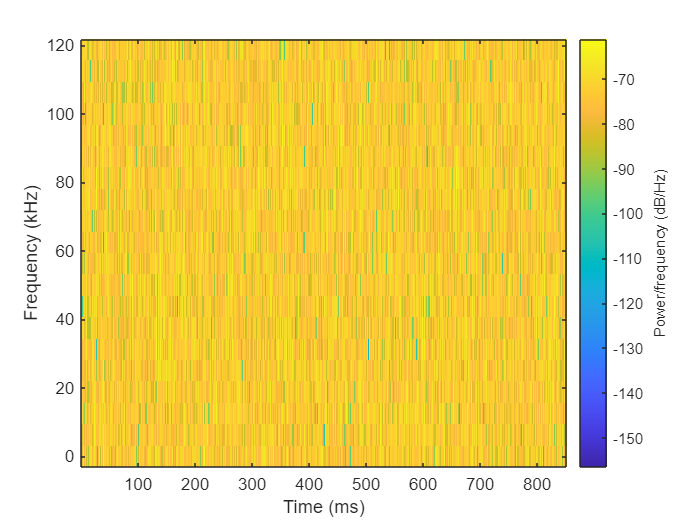

spectrogram(reshape(signal_data', 1, numel(signal_data))', seg_len, [], seg_len, Fs, 'yaxis');

## Demodulation

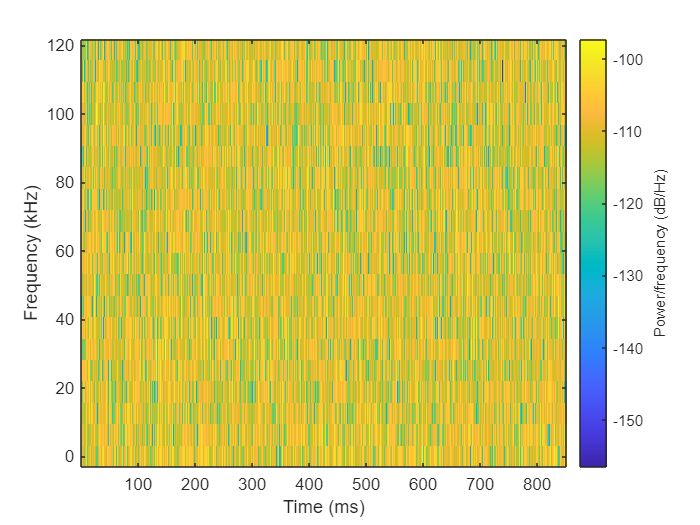

% Demodulation
received_data = reshape(signal_data, [], num_samples);  % Stores the received data, row-wise
base_down_chirp = zeros(1, num_samples);    % Will be used to demodulate the signal
dechirped_data = zeros(numel(received_data)/num_samples, num_samples);

% Generate the base-down chirp
k = 0;
for n = 1:num_samples
    if k >= 2^SF
        k = k-2^SF;
    end
    k = k + 1;
    base_down_chirp(n) = (1/(sqrt(2^SF)))*exp(-1i*2*pi*(k)*(k/(2^SF*2)));
end

payload = zeros(1, numel(received_data)/num_samples);   % Stores the transmitted data

% Perform demodulation symbol-wise (i.e. row-wise)
for i = 1:numel(received_data)/num_samples
    lora_symbol = received_data(i, :);
    
    dechirped = lora_symbol.*base_down_chirp;   % Demodulate the symbol
    dechirped_data(i, :) = dechirped;
    
    corrs = abs(fft(dechirped)).^2;             % Perform correlation
    
    % Obtain the correlated symbol
    [~, ind] = max(corrs);
    payload(i) = ind-1;
end

spectrogram(reshape(dechirped_data', 1, numel(dechirped_data))', seg_len, [], seg_len, Fs, 'yaxis');

demodulated_payload = payload(11:end)

demodulated_payload =     37   254   254     2    17   155    51     2    13   137    51   121   159   167   152    43


ciphertext

ciphertext =     37   254   254     2    17   155    51     2    13   137    51   121   159   167   152    43


## Bit Flipping (Man in the middle Attack)

bit_flipped = demodulated_payload;
%bit_flipped(4) = 100;
bit_flipped

bit_flipped =     37   254   254     2    17   155    51     2    13   137    51   121   159   167   152    43


## Decryption

decrypted_plaintext = inv_cipher(bit_flipped, w, inv_s_box, inv_poly_mat, 1)

 
********************************************
*                                          *
*       I N V E R S E   C I P H E R        *
*                                          *
********************************************
 
Initial state :                  25 11 0d 9f 
                                 fe 9b 89 a7 
                                 fe 33 33 98 
                                 02 02 79 2b 
 
Initial round key :              13 e3 f3 4d 
                                 11 94 07 2b 
                                 1d 4a a7 30 
                                 7f 17 8b c5 
 
State at start of round 9 :      36 f2 fe d2 
                                 ef 0f 8e 8c 
                                 e3 79 94 a8 
                                 7d 15 f2 ee 
 
After inv_shift_rows :           36 f2 fe d2 
                                 8c ef 0f 8e 
                                 94 a8 e3 79 
                                 15 f2 ee 7d 
 
After inv_sub_bytes :      

decrypted_plaintext =    123    84    58    50    52    67    44    32    83    79    67    58    54    53    37   125


char(decrypted_plaintext)

ans = '{T:24C, SOC:65%}'

plaintext_msg

plaintext_msg = "{T:24C, SOC:65%}"